**Exercise 4:**

Reducing ODE:


$$\begin{array}{l}
y\left(1\right)=x\\
\frac{d\left(y\left(1\right)\right)}{\mathrm{dt}}=\frac{\mathrm{dx}}{\mathrm{dt}}\\
y\left(2\right)=\frac{d\left(y\left(1\right)\right)}{\mathrm{dt}}\\
\frac{d\left(y\left(2\right)\right)}{\mathrm{dt}}=\frac{\left(d^2 \left(y\left(1\right)\right)\right)}{{\mathrm{dt}}^2 }
\end{array}$$


Then our system becomes:


$$m*\frac{\mathrm{dy}\left(2\right)}{\mathrm{dt}}+a*\mathrm{sign}\left(y\left(2\right)\right)*{\left(y\left(2\right)\right)}^2 +b*{y\left(1\right)}^3 =0$$


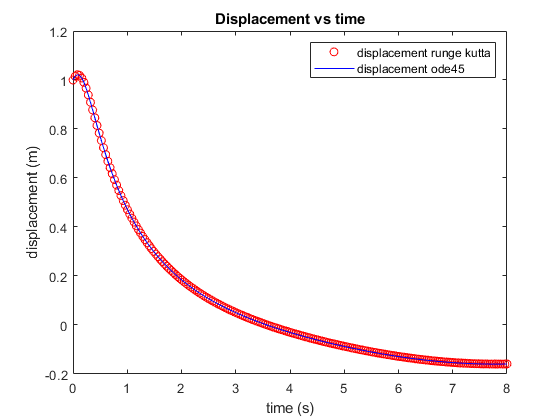

initialcond=[1; 0.5];
t=linspace(0,8,200);
func=@disp;
[result]=runge_kutta(func,t,initialcond);
displacement = result(1,:);
velocity = result(2,:);

[a b]=ode45(func,t,initialcond);
displacement_ode45=b(:,1);
velocity_ode45=b(:,2);

plot(t,displacement,'ro',t,displacement_ode45,'-b')
title('Displacement vs time');
legend('displacement runge kutta','displacement ode45');
xlabel('time (s)');
ylabel('displacement (m)');

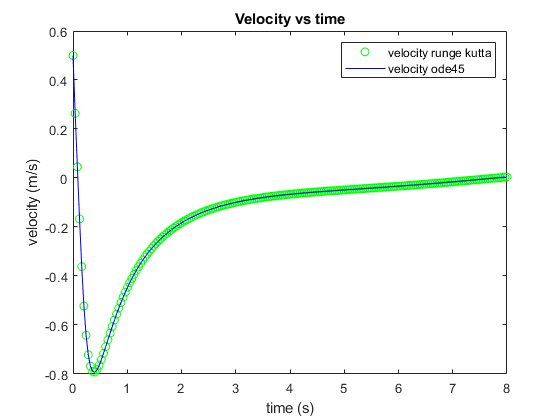


plot(t,velocity,'go',t,velocity_ode45,'-b')
title('Velocity vs time');
legend('velocity runge kutta','velocity ode45');
xlabel('time (s)');
ylabel('velocity (m/s)');

function [dydt]=disp(t,y)
dydt=zeros(2,1);
m=1;a=5;b=5;
dydt(1)=y(2);
dydt(2)=(-1/m)*(a*sign(y(2))*y(2)^2+b*y(1)^3);
end



function [y] = runge_kutta(df,x,y0)
m = length(y0);
n = length(x);
% y is a matrix of size 'mxn'
y=zeros(m,n);
y(:,1)=y0;
for i=1:n-1
    h = x(i+1)-x(i);
    xi=x(i);
    yi=y(:,i);
    k1 = feval(df,xi,yi);
    k2 = feval(df,xi+0.5*h,yi+0.5*k1*h);
    k3 = feval(df,xi+0.5*h,yi+0.5*k2*h);
    k4 = feval(df,xi+h,yi+k3*h);
    y(:,i+1) = y(:,i) + h*(k1+2*k2+2*k3+k4)/6;
end
end